## Low-Speed Steering Friction Torque between the Tire and Pavement

There is surface contact between the tire and pavement, as shown in Figure

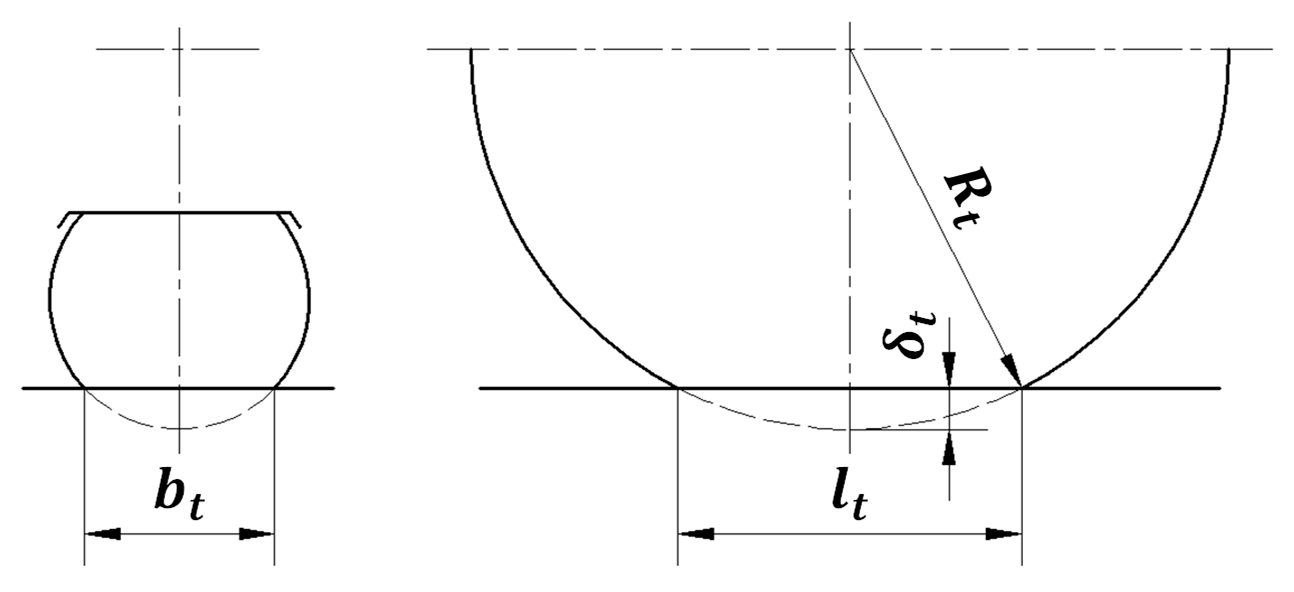

As the load increases, the tire will come into contact with the pavement over the entire width, and the contact region shape will become approximately elliptical and rectangular.

**Shape is considered to be rectangle.**

There is surface contact between the tire and pavement, as shown in Figure 4. Where **dt** is the deformation or subsidence of the tire, **lt** and **bt** are respectively the length and width of the tire/pavement contact region. The values of **dt**, **lt** and **bt** can be calculated by the following empirical formulas.

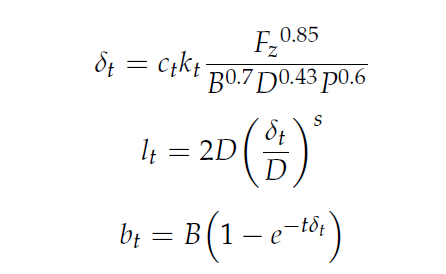

% Coefficients.

ct = 1.15; % For Bias or 1.5 for radial
B = 17.78; % Width of the tire in cm
kt = 0.015*B + 0.42;
Fz = 20; % Vertical Load on the tire in unit 10 N.
D = 292.12; % Diameter in cm
P = 300 % Pressure in unit kPa
s = 0.557;
t = 122.7
e = 2.71828;
c = 0.2 % kingpin offset in cm


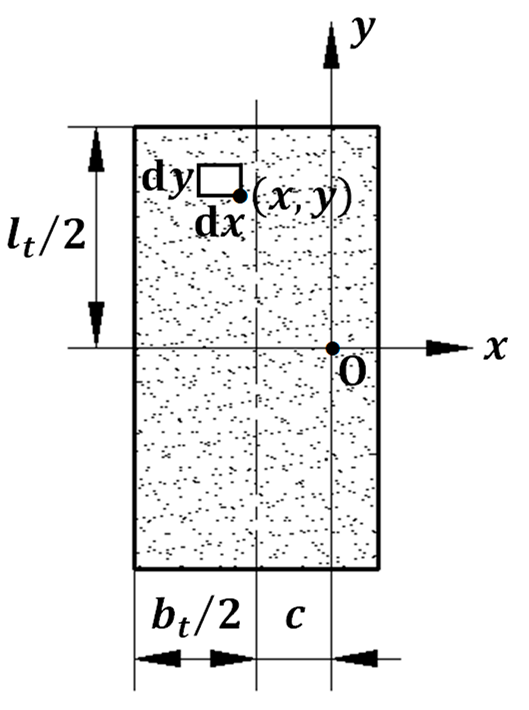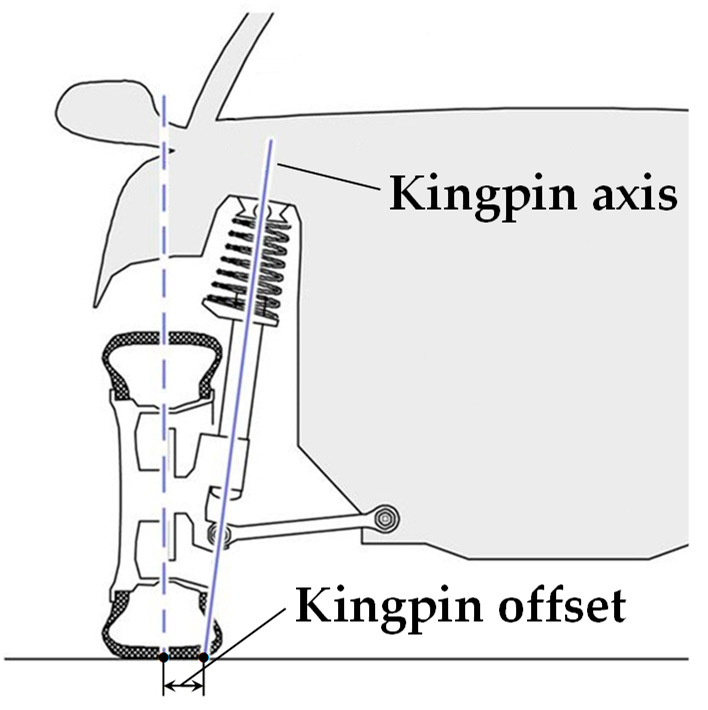


% Formulas:

dt = ct*kt*((Fz^0.85)/((B^0.7)*(D^0.43)*(P^0.6)));
lt = 2*D*(dt/D)^s;
bt = B*(1- e^(-t*dt));


**Now, Low Speed steering friction torque can be computed by:**

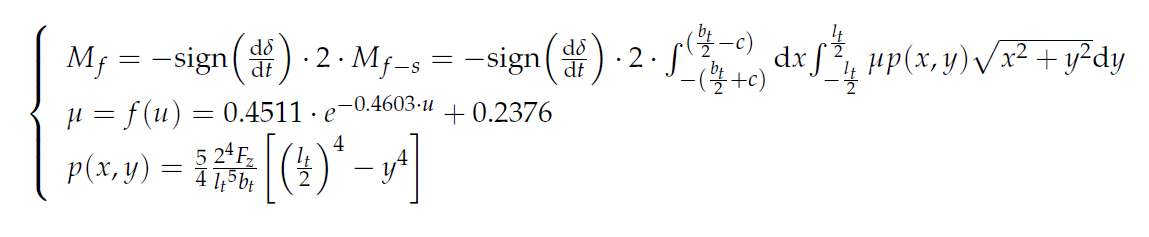

u = 5 % turning speed in km/h
mu = 0.4511 * e^(-0.4603*u) + 0.2376;
p = @(y) (((5)*(2^4)*(Fz))/(4* lt^5 * bt))* ((lt/2)^4 - y);
Mf = @(x,y) 2*mu*p(y)*sqrt(x^2 + y^2);

friction_torque = quad2d(Mf,bt/2-c, -(bt/2+ct), lt/2, -lt/2);











